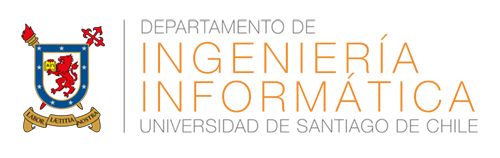

# Laboratorio 2 Señales

## PROCESAMIENTO DE SEÑALES E IMÁGENES

Profesores:

- Violeta Chang C.

- Alejandro Catalán.

Ayudante: Luis Corral

# Suma de convolución

La suma de convolución entre las señales $${h[n]}$$ y $x[n]$ está definida como (ver ejemplo 2.1 ):


$$y[n] = \sum_{-\infty}^{\infty} x[k] h[n-k]$$



$$y[n] = x[n] * h[n]$$


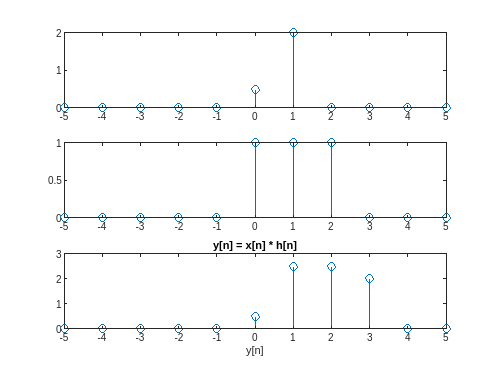

clearvars

n = -5:5;
N = length(n);
h_n = n>=0&n<=2;
x_n = zeros(1,N);
zv = find(n==0);
x_n(1,zv:zv+1) = [0.5 2];
y_n = zeros(1,N);
for i = 0:1
    y_n = y_n + x_n(1,zv+i)*circshift(h_n,i);
end

figure
subplot(3,1,1)
stem(n,x_n)
subplot(3,1,2)
stem(n,h_n)
subplot(3,1,3)
stem(n,y_n)
ylim([0 3])
title('y[n] = x[n] * h[n]')
xlabel('y[n]')

# La función conv

Una forma de representar la operación de convolución $y(t) = x(t) * h(t)$ de una señal $x(t)$ a un sistema LTI de respuesta al impulso $h(t)$, es mediante la función conv de Matlab. Debemos tener ciertas consideraciones, como los valores obtenidos en magnitud y el largo de la señal resultante $y(t)$. En este caso, podemos lograr una buena aproximación al ejemplo 2.6 de la referencia, utilizando la opción 'valid' para la función conv, la cual nos asegura tener resultados de igual largo y escalando la amplitud a uno y luego multiplicando por el factor $1/a$.

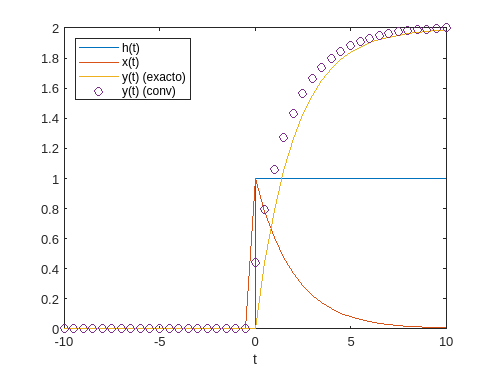

clearvars

t = -10:0.5:10;
a = 0.5;
x_t =  exp(-a*t).*(t>=0);
h_t = t>=0;
y_t_e = (1/a)*(1-exp(-a*t)).*(t>=0);
y_t_c = conv(x_t,h_t,'same');
y_t_c = (1/a)*(y_t_c/max(y_t_c));

figure
stairs(t,h_t)
hold on
plot(t,x_t,t,y_t_e)
hold on
plot(t,y_t_c,'o')
ylim([0 2])
xlabel('t')
legend('h(t)','x(t)','y(t) (exacto)','y(t) (conv)', ...
       'Location','NorthWest')

# Lectura de archivos y frecuencia de muestreo

Para leer una señal desde un archivo, utilizaremos la funcion [x_n,Fs] = audioread(filename), donde x_n es el vector con los valores para cada muestra, Fs es la frecuencia de muestreo y filename es el nombre de un archivo con extension .wav.

clearvars

[x_n,Fs] = audioread('44100Hz.wav');
x_n = x_n(1:Fs);

Con la frecuencia de muestreo podemos conocer los valores en segundos de la variable temporal.

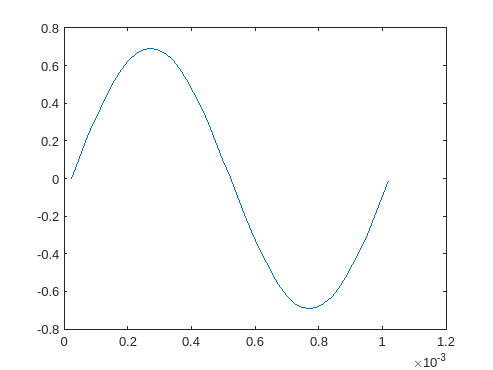

figure
plot_l = 45;
plot((1:plot_l)./Fs,x_n(1:plot_l))                       % 1 segundo dominio tiempo

# Ejercicio

Considere la relación $\omega_s = 2\pi f_s$, donde $f_s$ es la frecuencia de muestreo en Hertz. Obtenga la señal del archivo '44100Hz.wav' y su frecuencia de muestreo con el uso de la función [y,Fs] = audioread(filename) de Matlab. Grafique la señal en el tiempo y determine la frecuencia $\omega_0$ de la señal periódica.

# Referencias

[1] Oppenheim, A.V. & Willsky, A.S. & Nawab, S.H. (1997). Señales y sistemas (2nd ed.). Prentice Hall.